# Condition Monitoring and Prognostics using Vibration Signals

load pdmBearingConditionMonitoringData.mat;
load pdmBearingConditionMonitoringStatistics.mat
numSamples = length(data);
fs         = 20E3;       % sampling frequency

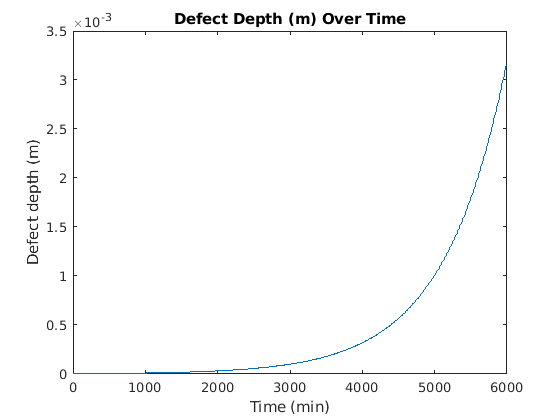

f1 = figure(1); clf;
plot(expTime,defectDepthVec);
xlabel('Time (min)');
ylabel('Defect depth (m)');
title('Defect Depth (m) Over Time');

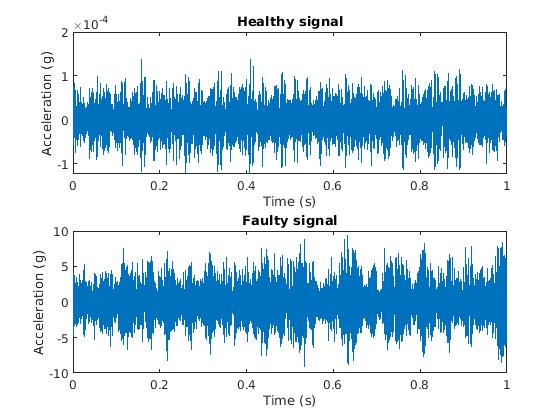

time = linspace(0,1,fs)';
f2   = figure(2); clf;

subplot(2,1,1);
plot(time,data{1}*.10197);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Healthy signal');

subplot(2,1,2);
plot(time,data{end}*.10197);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Faulty signal');

## Feature Extraction

- time domain features: rms, peak value, signal kurtosis, etc

- freq domain features: peak freq, mean freq, etc

Visualize signals with a spectrogram

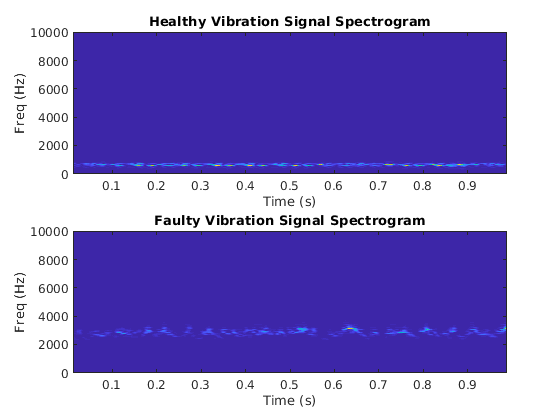

[~,healthy_freq_vector, healthy_time_vector, healthy_spectrogram] = spectrogram(data{1}, 500, 450, 512, fs);
[~,faulty_freq_vector, faulty_time_vector, faulty_spectrogram] = spectrogram(data{end}, 500, 450, 512, fs);

f3 = figure(3); clf;
subplot(211);
imagesc(healthy_time_vector, healthy_freq_vector, healthy_spectrogram);
xlabel('Time (s)');
ylabel('Freq (Hz)');
title("Healthy Vibration Signal Spectrogram");
axis xy;

subplot(212);
imagesc(faulty_time_vector, faulty_freq_vector, faulty_spectrogram);
xlabel('Time (s)');
ylabel('Freq (Hz)');
title("Faulty Vibration Signal Spectrogram");
axis xy;

Since we can clearly see a difference, we can extract the relavent features from the spectrograms for condition monitoring and prognostics.

## Extract the mean peak frequencies

[~,healthy_peak_locs]   = max(healthy_spectrogram);
[~,faulty_peak_locs]    = max(faulty_spectrogram);

healthy_mean_peak_freq = mean(healthy_freq_vector(healthy_peak_locs));
faulty_mean_peak_freq  = mean(faulty_freq_vector(faulty_peak_locs));

fprintf('healthy peak freq: %f', healthy_mean_peak_freq);

healthy peak freq: 666.460198

fprintf('faulty peak freq:  %f', faulty_mean_peak_freq);

faulty peak freq:  2806.805467

#### Do this for all samples now

% Define a progress bar.
h = waitbar(0,'Start to extract features');
% Initialize a vector to store the extracted mean peak frequencies.
meanPeakFreq = zeros(numSamples,1);
for k = 1:numSamples
    % Get most up-to-date data.
    curData = data{k};
    % Apply median filter.
    curDataFilt = medfilt1(curData,3);
    % Calculate spectrogram.
    [~,fvec,tvec,P_k] = spectrogram(curDataFilt,500,450,512,fs);
    % Calculate peak frequency at each time instance.
    [~,I] = max(P_k);
    meanPeakFreq(k) = mean(fvec(I));
    % Show progress bar indicating how many samples have been processed.
    waitbar(k/numSamples,h,'Extracting features');
end
close(h);

Plot the mean peak frequencies over time

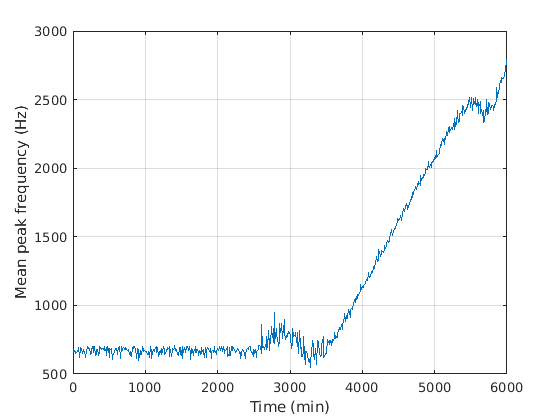

f4 = figure(4); clf;
plot(expTime,meanPeakFreq);
xlabel('Time (min)');
ylabel('Mean peak frequency (Hz)');
grid on;

## Condition Monitoring and Prognostics

- Condition Monitoring: create an alarm that triggers when the MPF exceeds a predefined threshold

- Prognostics: identify a dynamic model to forcast the values of the MPF in the next few hours and trigger

To define a threshold, we need the probability distributions

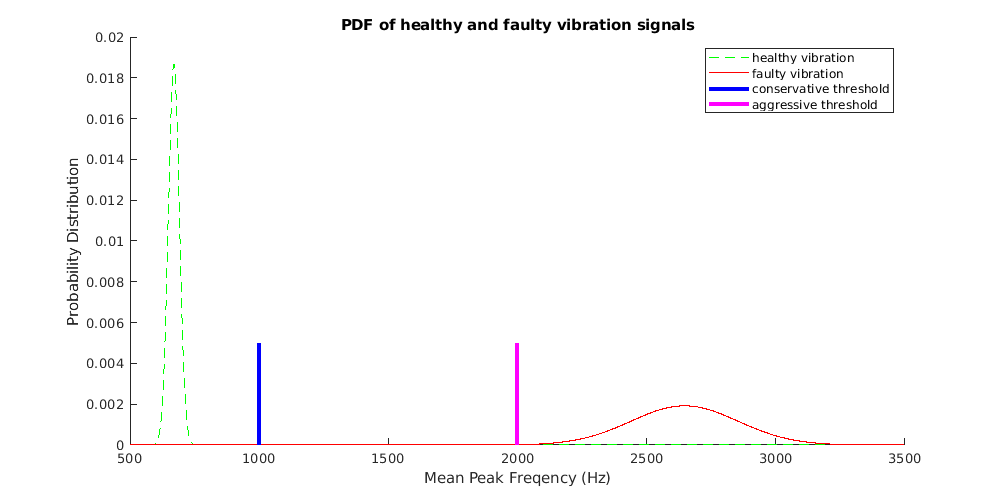

f5 = figure(5); clf;
f5.Position = [0 0 1000 500];
hold on;
plot(pFreq, pNormal, 'g--');
plot(pFreq, pFaulty, 'r');
plot([1000 1000], [0 .005], 'b', 'LineWidth', 3);
plot([2000 2000], [0 .005], 'm', 'LineWidth', 3);
hold off;
xlabel("Mean Peak Freqency (Hz)");
ylabel("Probability Distribution");
title("PDF of healthy and faulty vibration signals");
legend("healthy vibration", "faulty vibration", "conservative threshold", "aggressive threshold");

View the first 200 samples of the dataset (which will be used to create our initial model)

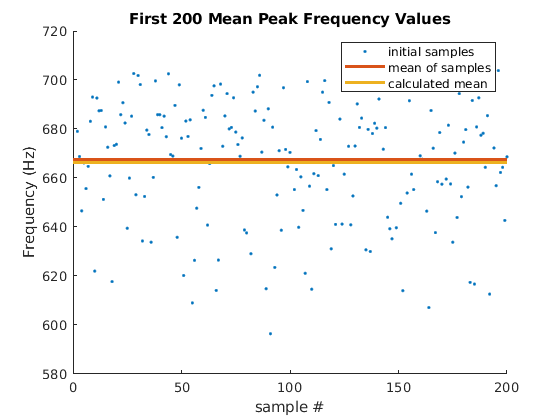

f6 = figure(6); clf;
hold on;
plot(tsFeature.y, '.');
plot([0 200], [mean(tsFeature.y) mean(tsFeature.y)], 'LineWidth', 2);
plot([0 200], [healthy_mean_peak_freq healthy_mean_peak_freq], 'LineWidth', 2);
hold off;
legend('initial samples', 'mean of samples', 'calculated mean'); 
title('First 200 Mean Peak Frequency Values');
xlabel('sample #');
ylabel('Frequency (Hz)');

Now use first 200 mpf vals to create the initial 2nd order time series model, then every 10 new updates, use the last 100 vals to update the model

threshold   = 1000;
fail_thresh = 2000;
tStart      = 200;               % Start Time
timeSeg     = 100;              % Length of data for building dynamic model
forecastLen = 10;           % Define forecast time horizon
batchSize   = 10;             % Define batch size for updating the dynamic model

samplingTime = 60*(expTime(2)-expTime(1));                  
tsFeature    = iddata(meanPeakFreq(1:tStart),[],samplingTime);

% discrete time model by specifying 'Ts', samplingTime
initial_sys  = ssest(tsFeature,2, 'Ts', samplingTime, 'Form', 'canonical')


initial_sys =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + K e(t)
       y(t) = C x(t) + e(t)
 
  A = 
            x1       x2
   x1        0        1
   x2   0.9605  0.03942
 
  C = 
       x1  x2
   y1   1   0
 
  K = 
              y1
   x1  -0.003899
   x2   0.003656
 
Sample time: 600 seconds
  
Parameterization:
   CANONICAL form with indices: 2.
   Disturbance component: estimate
   Number of free coefficients: 4
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using SSEST on time domain data "tsFeature".
Fit to estimation data: 0.2763% (prediction focus)    
FPE: 640, MSE: 602.7                                  


View the residuals (they should be uncorrelated)

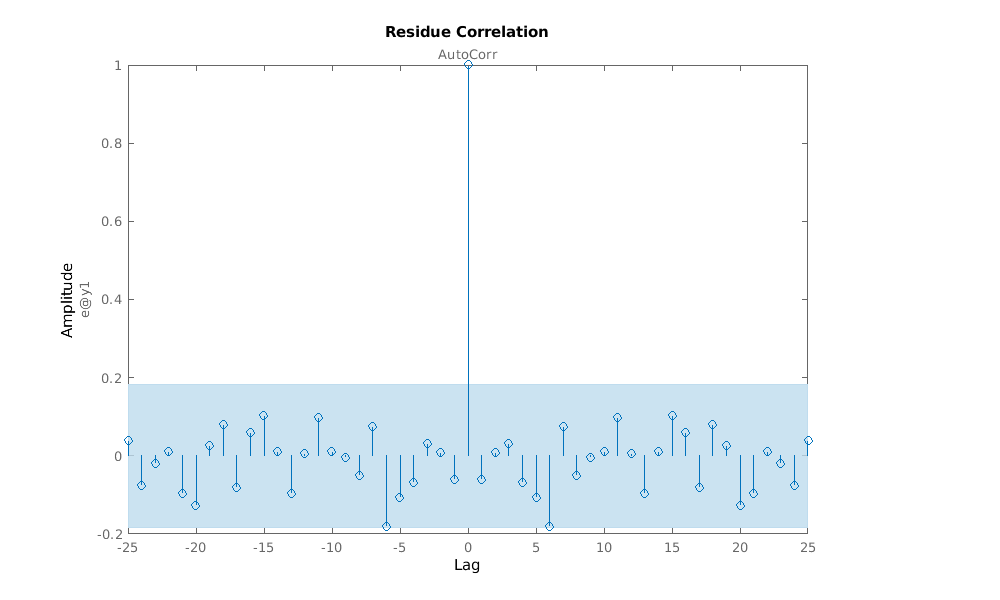

resid(tsFeature, initial_sys)

Looks good.

## Now forcast the next 10 samples

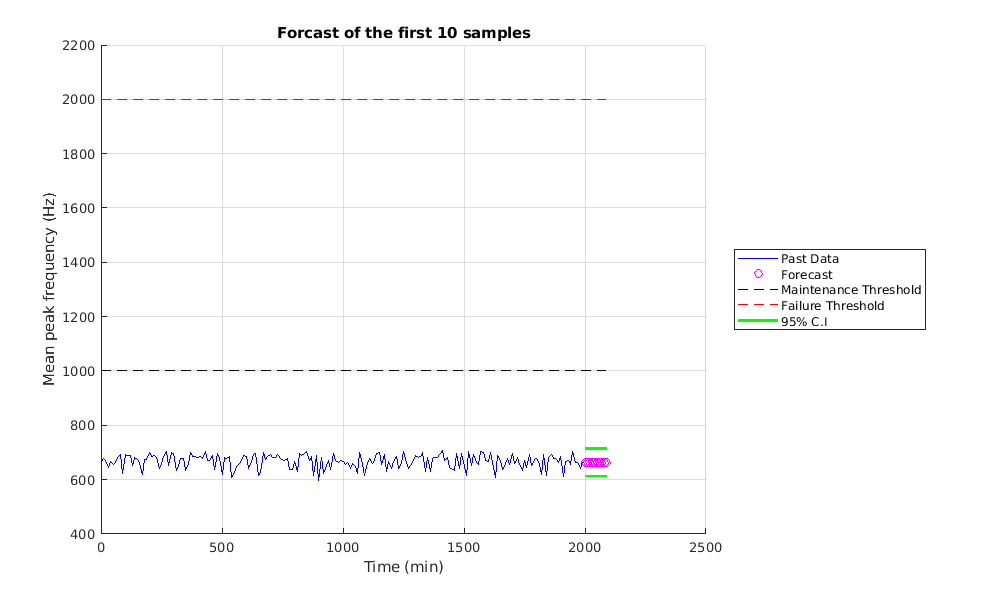

[yF,~,~,yFSD] = forecast(initial_sys,tsFeature,forecastLen);

tHistory = expTime(1:tStart);
forecastTimeIdx = (tStart+1):(tStart+forecastLen);
tForecast = expTime(forecastTimeIdx);

f7 = figure(7); clf;
f7.Position = [0 0 1000 600];
% Plot historical data, forecast value and 95% confidence interval.
hold on;
plot(tHistory,meanPeakFreq(1:tStart),'b');
plot(tForecast,yF.OutputData,'mo');
plot([tHistory; tForecast], threshold*ones(1,length(tHistory)+forecastLen), 'k--');
plot([tHistory; tForecast], fail_thresh*ones(1,length(tHistory)+forecastLen), 'r--');
plot(tForecast,yF.OutputData+1.96*yFSD,'g', 'LineWidth', 2);
plot(tForecast,yF.OutputData-1.96*yFSD,'g', 'LineWidth', 2);
hold off;

ylim([400, 1.1*fail_thresh]);
ylabel('Mean peak frequency (Hz)');
xlabel('Time (min)');
title('Forcast of the first 10 samples');
legend({'Past Data', 'Forecast', 'Maintenance Threshold', 'Failure Threshold', '95% C.I'},...
    'Location','eastoutside');
grid on;

## Perform the Experiment

Monitored variable reached maintenance threshold at: 3890 minutes.


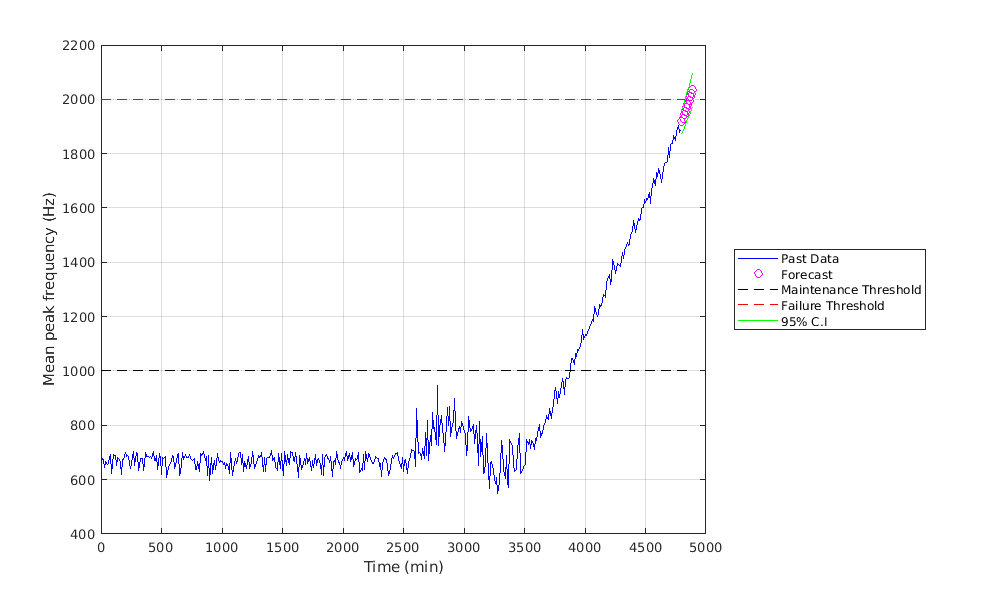

Estimated time to failure is: 80 minutes from now.


flag     = false;
past_sys = initial_sys;
for tCur = tStart:batchSize:numSamples
    %  latest features into iddata object.
    tsFeature = iddata(meanPeakFreq((tCur-timeSeg+1):tCur),[],samplingTime);
    
    % Update system parameters when new data comes in. Use previous model
    % parameters as initial guesses.
    sys = ssest(tsFeature,past_sys);
    past_sys = sys;
    
    % Forecast the output of the updated state-space model. Also compute
    % the standard deviation of the forecasted output.
    [yF,~,~,yFSD]  = forecast(sys, tsFeature, forecastLen);
    
    % Find the time corresponding to historical data and forecasted values.
    tHistory = expTime(1:tCur);
    forecastTimeIdx = (tCur+1):(tCur+forecastLen);
    tForecast = expTime(forecastTimeIdx);
    
    % Plot historical data, forecasted mean peak frequency value and 95%
    % confidence interval.
    plot(tHistory,meanPeakFreq(1:tCur),'b',...
              tForecast,yF.OutputData,'mo',...
              [tHistory; tForecast], threshold*ones(1,length(tHistory)+forecastLen), 'k--',...
              [tHistory; tForecast], fail_thresh*ones(1,length(tHistory)+forecastLen), 'r--',...
              tForecast,yF.OutputData+1.96*yFSD,'g',...
              tForecast,yF.OutputData-1.96*yFSD,'g');

          %     hold on;
%     plot(tHistory,meanPeakFreq(1:tCur),'b');
%     plot(tForecast,yF.OutputData,'mo');
%     plot([tHistory; tForecast], threshold*ones(1,length(tHistory)+forecastLen), 'k--');
%     plot([tHistory; tForecast], fail_thresh*ones(1,length(tHistory)+forecastLen), 'r--');
%     plot(tForecast,yF.OutputData+1.96*yFSD,'g', 'LineWidth', 2);
%     plot(tForecast,yF.OutputData-1.96*yFSD,'g', 'LineWidth', 2);
%     hold off;

    ylim([400, 1.1*fail_thresh]);
    ylabel('Mean peak frequency (Hz)');
    xlabel('Time (min)');
    legend({'Past Data', 'Forecast', 'Maintenance Threshold', 'Failure Threshold', '95% C.I'},...
           'Location','eastoutside');
    grid on;
    
    % Display an alarm when actual monitored variables or forecasted values exceed
    % failure threshold.
    if(any(meanPeakFreq(tCur-batchSize+1:tCur)>threshold) && ~flag)
        disp(['Monitored variable reached maintenance threshold at: ' num2str(tHistory(end)) ' minutes.']);
        flag = true;
    end
    if(any(yF.y>fail_thresh))
        % Estimate the time when the system will reach failure threshold.
        tAlarm = tForecast(find(yF.y>fail_thresh,1));
        disp(['Estimated time to failure is: ' num2str(tAlarm-tHistory(end)) ' minutes from now.']);
        break;
    end
end